Per prima cosa definiamo quante sono le coordinate generalizzate del robot:

n=4 

n = 4

**Ricordiamo che il tutto viene calcolato rispetto all' origine del frame definito**

Poi dobbiamo definire tutte le variabili simboliche di nostro utilizzo:

q = sym('q', [n, 1]);
for i=1:n
    nomeVariabile = ['q' num2str(i)];
    assignin('base', nomeVariabile,q(i,1));
end

L = sym('l', [n, 1]);
for i=1:n
    nomeVariabile = ['l' num2str(i)];
    assignin('base', nomeVariabile,L(i,1));
end

%inertia matrix for each link
I = sym('Ic', [3, 3, n]);
for i=1:n
    I(1,1,i)=sym(['Ic' num2str(i) 'xx']);I(1,2,i)=sym(['Ic' num2str(i) 'xy']); I(1,3,i)=sym(['Ic' num2str(i) 'xz']);
    I(2,1,i)=sym(['Ic' num2str(i) 'yx']);I(2,2,i)=sym(['Ic' num2str(i) 'yy']); I(2,3,i)=sym(['Ic' num2str(i) 'yz']);
    I(3,1,i)=sym(['Ic' num2str(i) 'zx']);I(3,2,i)=sym(['Ic' num2str(i) 'zy']); I(3,3,i)=sym(['Ic' num2str(i) 'zz']);
end

m = sym('m', [n, 1]);
for i=1:n
    nomeVariabile = ['m' num2str(i)];
    assignin('base', nomeVariabile,m(i,1));
end

pcx = sym('pcx', [1,n]);
for i=1:n
    nomeVariabile = ['pcx' num2str(i)];
    assignin('base', nomeVariabile,pcx(1,i));
end
pcy = sym('pcy', [1,n]);
for i=1:n
    nomeVariabile = ['pcy' num2str(i)];
    assignin('base', nomeVariabile,pcy(1,i));
end
pcz = sym('pcz', [1,n]);
for i=1:n
    nomeVariabile = ['pcz' num2str(i)];
    assignin('base', nomeVariabile,pcz(1,i));
end

pcz=subs(pcz,pcz,zeros(1,n));  % da cancellare se si vogliono fare calcoli con pcz

uni=ones(1,n);
com=[pcx;pcy;pcz;uni]

$$com = \left(\begin{array}{cccc} {\mathrm{pcx}}_{1} & {\mathrm{pcx}}_{2} & {\mathrm{pcx}}_{3} & {\mathrm{pcx}}_{4}\\ {\mathrm{pcy}}_{1} & {\mathrm{pcy}}_{2} & {\mathrm{pcy}}_{3} & {\mathrm{pcy}}_{4}\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

Adesso dobbiamo notare che molto spesso ci sono delle condizioni che semplificano la posizione del centro di massa.

**When the center of mass is located on the kinematics axis of the links **we can introduce other variables in order to characterize well the position of the center of mass. 

D = sym('dc', [n, 1]);
for i=1:n
    nomeVariabile = ['dc' num2str(i)];
    assignin('base', nomeVariabile,D(i,1));
end

Queste distanze vanno dal joint_i al CoM del frame i. Quindi per capirci, Il joint 1 è quello alla base del robot, e il link 1 è il primo, quello che connette il joint alla base con il joint 2. dc1 è la distanza fra il joint1 e il centro di massa e cosi via.

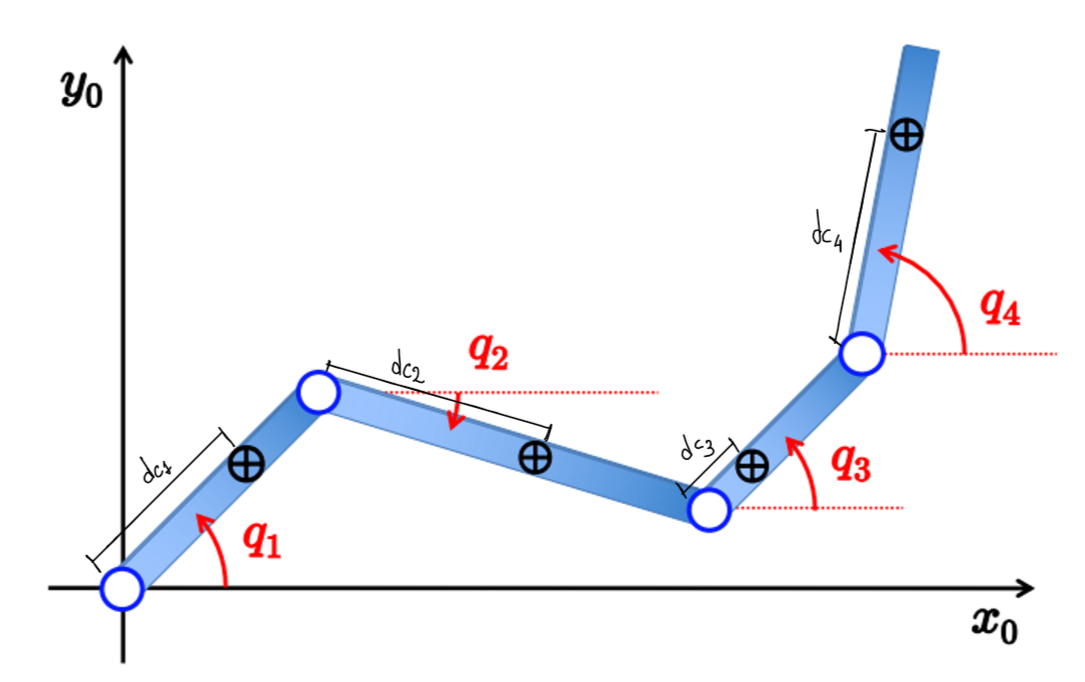

Purtroppo come assegnare i parametri dc alle variabili del vettore com va fatto a mano, perche cisono troppe complicazioni nel farlo in matlab e si rischia di sbagliare 

%assegnazioni rispetto i lframe di base
%assegnamo la prima posizione del centro di massa:
com(1,1)= dc1*(cos(q1));    %pcx1
com(2,1)=dc1*(sin(q1));     %pcy1      
com(3,1)=0;                 %pcz1         %era zero e rimane zero 

%assegnamo la prima posizione del centro di massa:
com(1,2)=l1*(cos(q1))+dc2*cos(q2);    %pcx2
com(2,2)=l1*(sin(q1))+dc2*sin(q2);    %pcy2      
com(3,2)=0;                           %pcz2         %era zero e rimane zero 


%assegnamo la prima posizione del centro di massa:
com(1,3)= l1*(cos(q1))+l2*cos(q2)+dc3*cos(q3);      %pcx3
com(2,3)=l1*(sin(q1))+l2*sin(q2)+dc3*sin(q3);       %pcy3
com(3,3)=0;                                         %pcz3       %era zero e rimane zero 

%assegnamo la prima posizione del centro di massa:
com(1,4)=l1*(cos(q1))+l2*cos(q2)+l3*cos(q3)+dc4*cos(q4);        %pcx4
com(2,4)=l1*(sin(q1))+l2*sin(q2)+l3*sin(q3)+dc4*sin(q4);        %pcy4
com(3,4)=0;                                                     %pcz4       %era zero e rimane zero 

com

$$com = \left(\begin{array}{cccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right) & {\mathrm{dc}}_{4}\,\cos\left(q_{4}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)+l_{3}\,\cos\left(q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right) & {\mathrm{dc}}_{4}\,\sin\left(q_{4}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right)+l_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

Ora che abbiamo tutte le posizioni procediamo con il calcolo dell' energia cinetica. Qui non possiamo usare i moving frames in quanto non abbiamo la notazione con D-H, NECESSARIA PER I MOVING FRAMES

Ricorda che:


$$T_i=\frac{1}{2}m_i \ v_{cm_i}^T \ v_{cm_i}\ + \ \frac{1}{2}\omega_i^T \ I_{cm_i} \ \omega_i$$


**dove per calcolare **$\mathbf{V_{cm_i}}$** devo tenere in considerazione del contributo fornito dai joint precedenti al joint i, mentre per calcolare **$\mathbf{\omega_i}$** devo considerare solo il contributo del joint i**

%components of kinetic energy:
t = sym('T', [n,1]);
qd = sym('qd', [n, 1]);
for i=1:n
    nomeVariabile = ['qd' num2str(i)];
    assignin('base', nomeVariabile,qd(i,1));
end


%calcolo di T1, dove omega è stata inserita a mano perche non posso capire
%a priori che direzione ha
pcm1=[com(1,1);com(2,1);com(3,1)]; %pcx1;pcy1;pcz1
vcm1=diff(pcm1,q1)*qd1;
trasl_partT1=1/2*m1*simplify(transpose(vcm1)*vcm1);
omegacm1=[0;0;qd1];
rot_partT1=1/2*transpose(omegacm1)*I(:,:,1)*omegacm1;
T1=simplify(rot_partT1+trasl_partT1)

$$T1 = \frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+\mathrm{Ic1zz}\right)}{2}$$

%calcolo di T2
pcm2=[com(1,2);com(2,2);com(3,2)]; %pcx2;pcy2;pcz2
vcm2=diff(pcm2,q1)*qd1+diff(pcm2,q2)*qd2;
trasl_partT2=1/2*m2*simplify(transpose(vcm2)*vcm2);
omegacm2=[0;0;qd2];
rot_partT2=1/2*transpose(omegacm2)*I(:,:,2)*omegacm2;
T2=simplify(rot_partT2+trasl_partT2)

$$T2 = \frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({\left({\mathrm{dc}}_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)\right)}^{2}+{\left({\mathrm{dc}}_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)\right)}^{2}\right)}{2}$$


%calcolo di T3
pcm3=[com(1,3);com(2,3);com(3,3)]; %pcx3;pcy3;pcz3
vcm3=diff(pcm3,q1)*qd1+diff(pcm3,q2)*qd2+diff(pcm3,q3)*qd3;
trasl_partT3=1/2*m3*simplify(transpose(vcm3)*vcm3);
omegacm3=[0;0;qd3];
rot_partT3=1/2*transpose(omegacm3)*I(:,:,2)*omegacm3;
T3=simplify(rot_partT3+trasl_partT3)

$$T3 = \frac{m_{3}\,\left({\left({\mathrm{dc}}_{3}\,{\mathrm{qd}}_{3}\,\sin\left(q_{3}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}+{\left({\mathrm{dc}}_{3}\,{\mathrm{qd}}_{3}\,\cos\left(q_{3}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{3}}^{2}}{2}$$

%calcolo di T4
pcm4=[com(1,4);com(2,4);com(3,4)]; %pcx4;pcy4;pcz4
vcm4=diff(pcm4,q1)*qd1+diff(pcm4,q2)*qd2+diff(pcm4,q3)*qd3+diff(pcm4,q4)*qd4;
trasl_partT4=1/2*m4*simplify(transpose(vcm4)*vcm4);
omegacm4=[0;0;qd4];
rot_partT4=1/2*transpose(omegacm4)*I(:,:,2)*omegacm4;
T4=simplify(rot_partT4+trasl_partT4)

$$T4 = \frac{m_{4}\,\left({\left({\mathrm{dc}}_{4}\,{\mathrm{qd}}_{4}\,\sin\left(q_{4}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)+l_{3}\,{\mathrm{qd}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}+{\left({\mathrm{dc}}_{4}\,{\mathrm{qd}}_{4}\,\cos\left(q_{4}\right)+l_{1}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)+l_{3}\,{\mathrm{qd}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{4}}^{2}}{2}$$

T=T1+T2+T3+T4;

Adesso dobbiamo ricavare la matrice M:

M(1,1)=simplify(diff(T,qd1,2));
M(2,2)=simplify(diff(T,qd2,2));
M(3,3)=simplify(diff(T,qd3,2));
M(4,4)=simplify(diff(T,qd4,2));
M(2,1)=simplify(diff(diff(T,q1),q2));
M(3,1)=simplify(diff(diff(T,q1),q3));
M(4,1)=simplify(diff(diff(T,q1),q4));
M(3,2)=simplify(diff(diff(T,q2),q3));
M(4,2)=simplify(diff(diff(T,q2),q4));
M(4,3)=simplify(diff(diff(T,q3),q4));
%M è simmetrica quindi:
M(1,2)=M(2,1);
M(1,3)=M(3,1);
M(1,4)=M(4,1);
M(2,3)=M(3,2);
M(2,4)=M(4,2);
M(3,4)=M(4,3);

M

$$M = \begin{array}{l} \left(\begin{array}{cccc} \mathrm{Ic1zz}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4} & \sigma_{1} & \sigma_{3} & \sigma_{6}\\ \sigma_{1} & \mathrm{Ic2zz}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4} & \sigma_{2} & \sigma_{5}\\ \sigma_{3} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{4}\,{l_{3}}^{2}+\mathrm{Ic2zz} & \sigma_{4}\\ \sigma_{6} & \sigma_{5} & \sigma_{4} & m_{4}\,{{\mathrm{dc}}_{4}}^{2}+\mathrm{Ic2zz} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\cos\left(q_{1}-q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ \sigma_{2}=l_{2}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\,\cos\left(q_{2}-q_{3}\right)\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{3}=l_{1}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\,\cos\left(q_{1}-q_{3}\right)\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{4}={\mathrm{dc}}_{4}\,l_{3}\,m_{4}\,{\mathrm{qd}}_{3}\,{\mathrm{qd}}_{4}\,\cos\left(q_{3}-q_{4}\right)\\ \sigma_{5}={\mathrm{dc}}_{4}\,l_{2}\,m_{4}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{4}\,\cos\left(q_{2}-q_{4}\right)\\ \sigma_{6}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{4}\,\cos\left(q_{1}-q_{4}\right) \end{array}$$

Adesso il nostro obiettivo è quello di torvare l' espressione della matrice di inerzia del robot quando però sono usate i D-H frames that uses $\theta$ as generalized cordinates.

Prima cosa da fare:

trovare la relazione che lega le coordinate $\theta$ usate in D-H e le cordinate generalizzate *q* utilizzate per ricavare M:

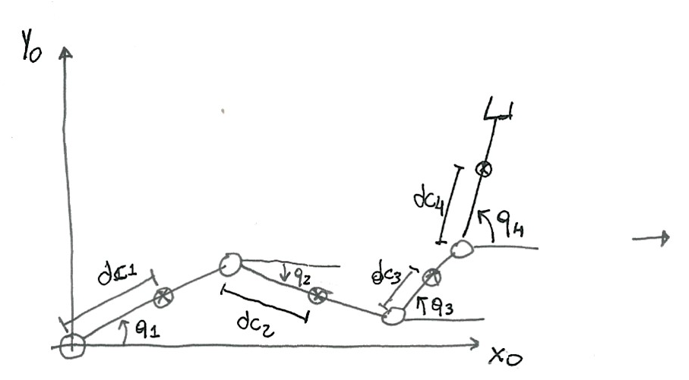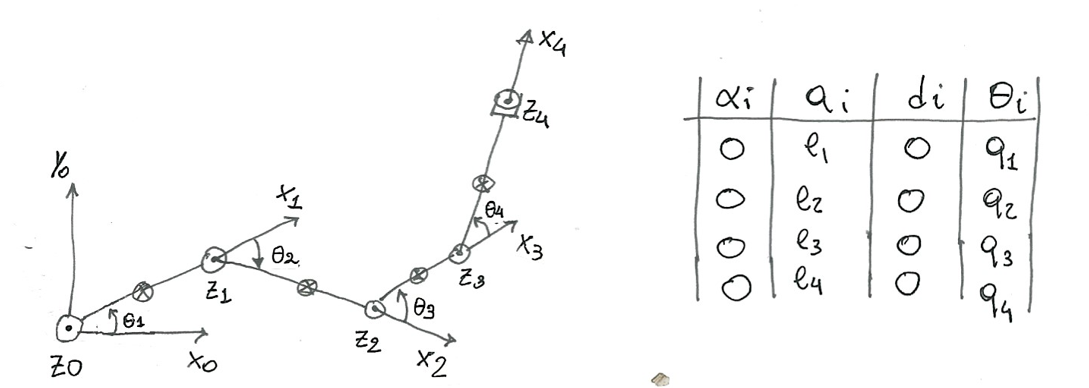

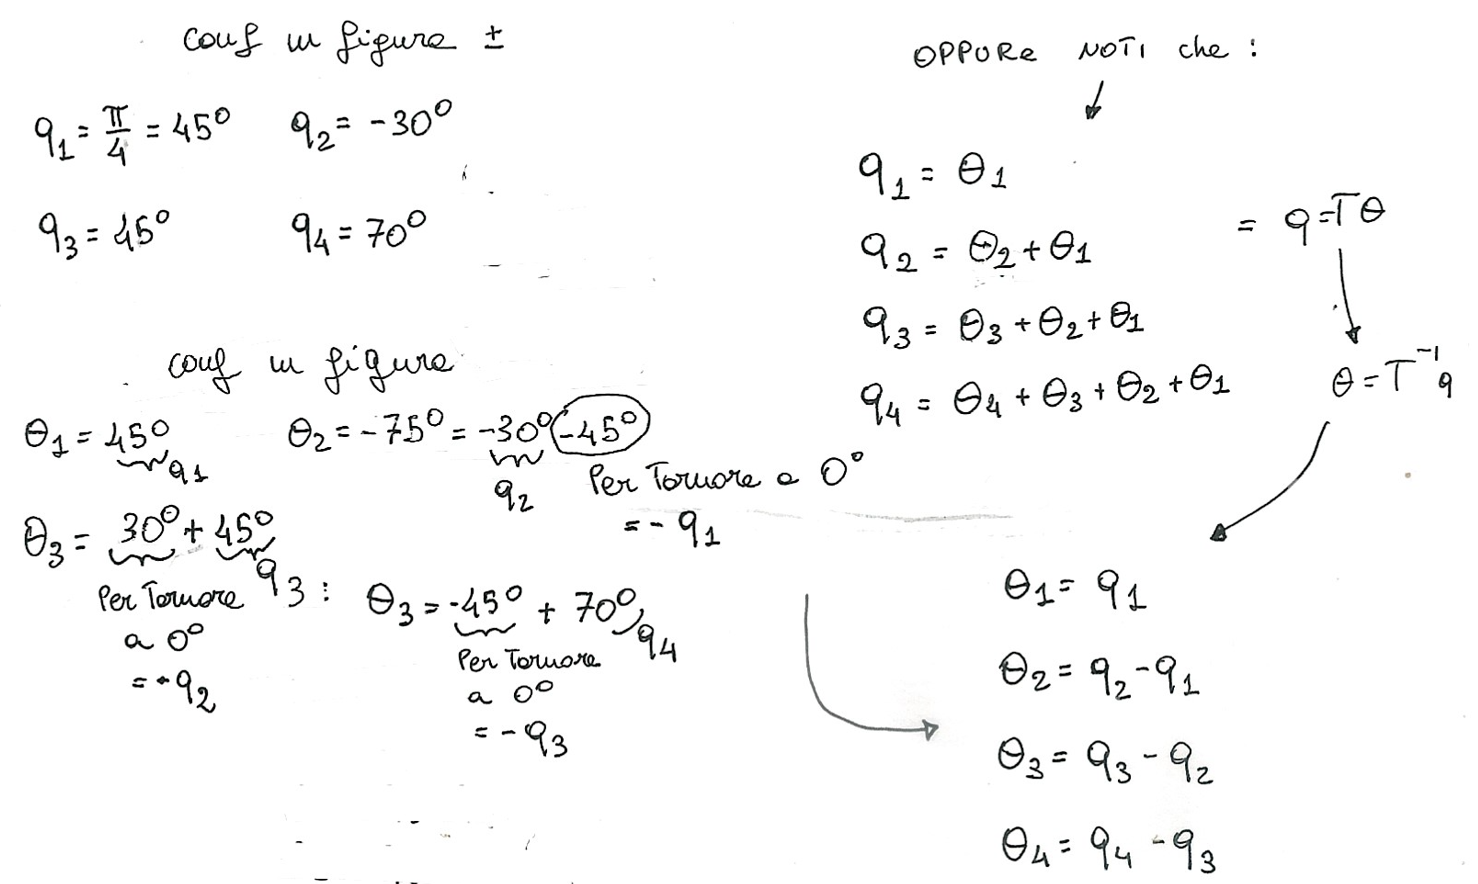

Nota che quando le coordinate generalizzate di partenza sono Assolute, questo risultato è sempre vero, in caso di robot formato da soli joint rotazionali.

Le relazioni da utilizzare sono:


$$q=T\theta \quad \quad \theta=T^{-1}q$$


theta = sym('theta', [n, 1]);
for i=1:n
    nomeVariabile = ['theta' num2str(i)];
    assignin('base', nomeVariabile,theta(i,1));
end

trasfCordMat=[1 0 0 0; 1 1 0 0 ; 1 1 1 0; 1 1 1 1]; %T-1
qq=trasfCordMat*theta;
trasfCordMatINV=inv(trasfCordMat); %T
theta=trasfCordMatINV*q

$$theta = \left(\begin{array}{c} q_{1}\\ q_{2}-q_{1}\\ q_{3}-q_{2}\\ q_{4}-q_{3} \end{array}\right)$$

Per ottenere la matrice di inerzia espressa in the $\theta$ cordinates we have to evaluate:


$$\tilde{M}(\theta)= T^TM(q)|_{q=T\theta}T$$



%prima di porcedere con l' effettivo cambio di cordinate, eseguiamolo prima
%considerando M completamente simbolica, in modo da riuscire almeno a
%visualizzare i risultati.


MM=sym('mm',[n,n]);
for k=1:n
    for i=1:n
        if(i>=k)
            nomeVariabile = ['mm' num2str(k) num2str(i)];
            assignin('base', nomeVariabile,MM(i,k));
        else
            MM(i,k)=MM(k,i);
        end

    end
end
MM

$$MM = \left(\begin{array}{cccc} {\mathrm{mm}}_{1,1} & {\mathrm{mm}}_{2,1} & {\mathrm{mm}}_{3,1} & {\mathrm{mm}}_{4,1}\\ {\mathrm{mm}}_{2,1} & {\mathrm{mm}}_{2,2} & {\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{4,2}\\ {\mathrm{mm}}_{3,1} & {\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{3,3} & {\mathrm{mm}}_{4,3}\\ {\mathrm{mm}}_{4,1} & {\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,4} \end{array}\right)$$

MMtheta=simplify(transpose(trasfCordMatINV)*MM*trasfCordMatINV)

$$MMtheta = \left(\begin{array}{cccc} {\mathrm{mm}}_{1,1}-2\,{\mathrm{mm}}_{2,1}+{\mathrm{mm}}_{2,2} & {\mathrm{mm}}_{2,1}-{\mathrm{mm}}_{2,2}-{\mathrm{mm}}_{3,1}+{\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{3,1}-{\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{4,1}+{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,1}-{\mathrm{mm}}_{4,2}\\ {\mathrm{mm}}_{2,1}-{\mathrm{mm}}_{2,2}-{\mathrm{mm}}_{3,1}+{\mathrm{mm}}_{3,2} & {\mathrm{mm}}_{2,2}-2\,{\mathrm{mm}}_{3,2}+{\mathrm{mm}}_{3,3} & {\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{3,3}-{\mathrm{mm}}_{4,2}+{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,2}-{\mathrm{mm}}_{4,3}\\ {\mathrm{mm}}_{3,1}-{\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{4,1}+{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{3,2}-{\mathrm{mm}}_{3,3}-{\mathrm{mm}}_{4,2}+{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{3,3}-2\,{\mathrm{mm}}_{4,3}+{\mathrm{mm}}_{4,4} & {\mathrm{mm}}_{4,3}-{\mathrm{mm}}_{4,4}\\ {\mathrm{mm}}_{4,1}-{\mathrm{mm}}_{4,2} & {\mathrm{mm}}_{4,2}-{\mathrm{mm}}_{4,3} & {\mathrm{mm}}_{4,3}-{\mathrm{mm}}_{4,4} & {\mathrm{mm}}_{4,4} \end{array}\right)$$

%vero cambio di coordinate, può impiegare un po di tempo 
Mtheta=simplify(transpose(trasfCordMat)*simplify(subs(M,q,trasfCordMat*theta))*trasfCordMat)